## Задание 1. Компенсирующий регулятор по состоянию.

function [eigenvalues, controllability_result] = analyze_controllability(A, B)
    eigenvalues = eig(A);
    controllability_result = true;
    
    disp('Eigenvalues of A:');
    disp(eigenvalues);
    
    for i = 1:length(eigenvalues)
        H = [eigenvalues(i) * eye(size(A)) - A, B]
        rank_H = rank(H)
        fprintf('Eigenvalue %d %di', real(eigenvalues(i)), imag(eigenvalues(i)));
        if rank_H < size(A, 1)
            controllability_result = false;
            fprintf(' is not controllable.\n');
        else
            fprintf(' is controllable.\n');
        end
    end
    
    if controllability_result
        disp('The system is fully controllable.');
    else
        disp('The system is not fully controllable.');
    end
end

function [J1, Bj, P1] = j_stuff_B(A, B)
    [P, J] = jordan(A);
    [P1, J1] = cdf2rdf(P, J);

    disp('Вещественная жорданова форма матрицы A:');
    disp(J1);

    disp('Вещественная P:');
    disp(P1);

    disp('Вещественная P^{-1}:');
    disp(inv(P1));

    disp('Новая матрица B:');
    Bj = P1\B;
    disp(Bj); 
end

function observable(A, C)
    Ob = obsv(A, C);
    rank_Ob = rank(Ob);
    if rank_Ob == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end

function [K] = get_K(A, B, G, Y)
    % Solve for K using CVX    
    cvx_begin sdp
        variable P(size(A, 1), size(A, 1))
        A*P-P*G == B*Y;
    cvx_end
    K = -Y*pinv(P);
end

function [K2] = get_K2(A, B1, B2, G, C, D, K1)
    cvx_begin sdp
        variable P(size(A, 1), size(G, 1))
        variable Y(size(B1, 2), size(B2, 2))
        P*G-A*P==B1*Y+B2;
        C*P==-D;
    cvx_end
    K2 = Y-K1*P;
end

function sim_sys(A, B, Bf, K1, K2, G, x0, wf0, simtime)
    assignin('base', 'A', A);
    assignin('base', 'B', B);
    assignin('base', 'Bf', Bf);
    assignin('base', 'K1', zeros(size(K1)));
    assignin('base', 'K2', zeros(size(K2)));
    assignin('base', 'G', G);
    assignin('base', 'x0', x0);
    assignin('base', 'wf0', wf0);

    % Simulink model name
    model_name = 'task1';
    load_system(model_name);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t = sim_out.tout;
    x = sim_out.yout{1}.Values.Data;
    wf = sim_out.yout{3}.Values.Data;
    z = sim_out.yout{4}.Values.Data;

    % No control
    figure('Position', [0 0 500 900]);

    m = 3;

    subplot(m, 1, 1);
    plot(t, wf, 'LineWidth', 1.5);
    title('Внешнее возмущение');
    xlabel('Время, с');
    ylabel('w_f(t)');
    grid on;

    subplot(m, 1, 2);
    plot(t, x, 'LineWidth', 1.5);
    title('Состояние');
    xlabel('Время, с');
    ylabel('x(t)');
    grid on;

    subplot(m, 1, 3);
    plot(t, z, 'LineWidth', 1.5);
    title('Виртуальный выход');
    xlabel('Время, с');
    ylabel('z(t)');
    grid on;

    exportgraphics(gcf, ['figs/task1_1.png'], 'Resolution', 500);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    assignin('base', 'K1', K1);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t1 = sim_out.tout;
    x1 = sim_out.yout{1}.Values.Data;
    u1 = sim_out.yout{2}.Values.Data;
    z1 = sim_out.yout{4}.Values.Data;

    assignin('base', 'K2', K2);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t2 = sim_out.tout;
    x2 = sim_out.yout{1}.Values.Data;
    u2 = sim_out.yout{2}.Values.Data;
    z2 = sim_out.yout{4}.Values.Data;

    figure('Position', [0 0 900 900]);

    m = 3;
    n = 3;

    subplot(m, n, [1,2,3]);
    plot(t1, u1, 'LineWidth', 1.5); hold on;
    plot(t2, u2, 'LineWidth', 1.5);
    title('Управление');
    xlabel('Время, с');
    ylabel('u(t)');
    legend("K1", "K1 & K2", 'Location', 'eastoutside');
    grid on;

    subplot(m, n, 4);
    plot(t1, x1(:, 1), 'LineWidth', 1.5); hold on;
    plot(t2, x2(:, 1), 'LineWidth', 1.5);
    title('Состояние 1');
    xlabel('Время, с');
    ylabel('x_1(t)');
    grid on;

    subplot(m, n, 5);
    plot(t1, x1(:, 2), 'LineWidth', 1.5); hold on;
    plot(t2, x2(:, 2), 'LineWidth', 1.5);
    title('Состояние 2');
    xlabel('Время, с');
    ylabel('x_2(t)');
    grid on;

    subplot(m, n, 6);
    plot(t1, x1(:, 3), 'LineWidth', 1.5); hold on;
    plot(t2, x2(:, 3), 'LineWidth', 1.5);
    title('Состояние 3');
    xlabel('Время, с');
    ylabel('x_3(t)');
    grid on;

    subplot(m, n, [7,8,9]);
    plot(t1, z1, 'LineWidth', 1.5); hold on;
    plot(t2, z2, 'LineWidth', 1.5);
    title('Виртуальный выход');
    xlabel('Время, с');
    ylabel('z(t)');
    grid on;

    exportgraphics(gcf, ['figs/task1_2.png'], 'Resolution', 500);
end

A = [        3 5 4;
        -2 -4 -5;
        2 2 3];
B = [2;-1;1];
Bf = [        -2 0 0 2;
        -2 0 0 0;
        0 0 0 0];
G = [        35 56 22 -42;
        -11 -17 -7 12;
        -6 -10 -5 10;
        11 18 6 -13];
CZ = [2 3 3];

eig(G)

ans =    0.0000 + 3.0000i
   0.0000 - 3.0000i
  -0.0000 + 1.0000i
  -0.0000 - 1.0000i


analyze_controllability(A, B);

Eigenvalues of A:
   2.0000 + 1.0000i
   2.0000 - 1.0000i
  -2.0000 + 0.0000i



H =   -1.0000 + 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   2.0000 + 0.0000i   6.0000 + 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 + 1.0000i   1.0000 + 0.0000i


rank_H = 3

Eigenvalue 2 1.000000e+00i is controllable.


H =   -1.0000 - 1.0000i  -5.0000 + 0.0000i  -4.0000 + 0.0000i   2.0000 + 0.0000i
   2.0000 + 0.0000i   6.0000 - 1.0000i   5.0000 + 0.0000i  -1.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 - 1.0000i   1.0000 + 0.0000i


rank_H = 3

Eigenvalue 2 -1.000000e+00i is controllable.


H =    -5.0000   -5.0000   -4.0000    2.0000
    2.0000    2.0000    5.0000   -1.0000
   -2.0000   -2.0000   -5.0000    1.0000


rank_H = 2

Eigenvalue -2.000000e+00 0i is not controllable.
The system is not fully controllable.


[AJ, BJ, P] = j_stuff_B(A, B);

Вещественная жорданова форма матрицы A:
    -2     0     0
     0     2    -1
     0     1     2

Вещественная P:
   -1.0000    0.7071   -0.7071
    1.0000   -1.4142         0
         0    1.4142         0

Вещественная P^{-1}:
         0    1.0000    1.0000
         0         0    0.7071
   -1.4142   -1.4142   -0.7071

Новая матрица B:
         0
    0.7071
   -2.1213



Aj = [2 -1;
    1 2];
Bj = [0.7071; -2.1213];
Gr = [-10 1;
    0 -10];
Y = [1 0];
observable(Gr, Y)

YES


Kj = get_K(Aj, Bj, Gr, Y)

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


Kj =   -64.0645  -10.0410


KJ = [0 Kj];
eig(AJ+BJ*KJ)

ans =    -9.9628
  -10.0374
   -2.0000


K=KJ/P

K =    14.2001   14.2001  -38.2004


eig(A+B*K)

ans =    -9.9628
  -10.0374
   -2.0000


K2 = get_K2(A, B, Bf, G, CZ, 0, K)

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|7.8e-01|2.9e+03|5.2e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  2  2 
 1|1.000|0.894|3.4e-02|3.1e+02|1.6e+04| 0.000000e+00  3.766264e+03| 0:0:00| chol  1  2 
 2|1.000|0.982|8.0e-05|5.6e+00|1.5e+02| 0.000000e+00  5.872763e+01| 0:0:00| chol  1  1 
 3|1.000|0.989|1.7e-06|6.3e-02|1.4e+00| 0.000000e+00  6.770703e-01| 0:0:00| chol  1  1 
 4|1.000|0.98

K2 =  -616.3844 -913.3667 -408.5065  751.0739


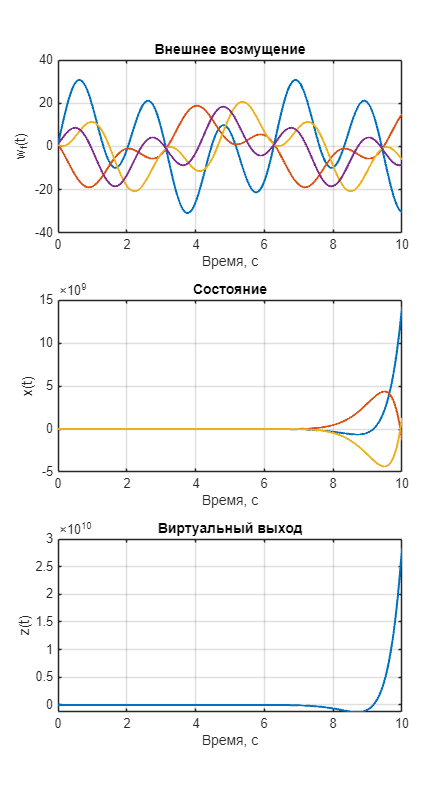

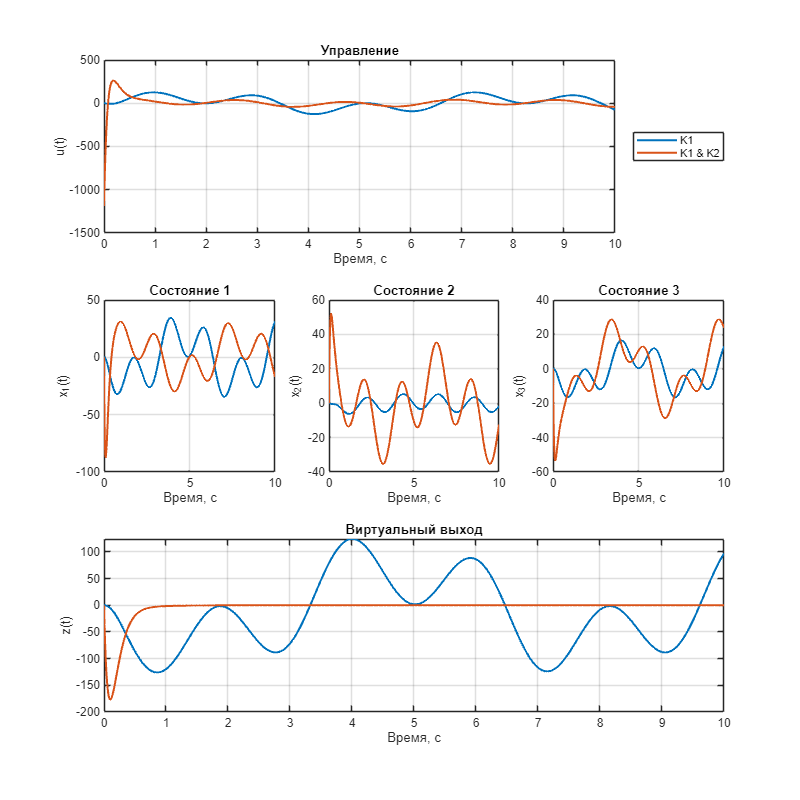

x0 = [0; 0; 0];
wf0 = [1; 1; 1; 1];
sim_sys(A, B, Bf, K, K2, G, x0, wf0, 10);

## Задание 2. Следящий регулятор по состоянию.

function sim_sys2(A, B, K1, K2, G, x0, wg0, simtime)
    assignin('base', 'A', A);
    assignin('base', 'B', B);
    assignin('base', 'K1', zeros(size(K1)));
    assignin('base', 'K2', zeros(size(K2)));
    assignin('base', 'G', G);
    assignin('base', 'x0', x0);
    assignin('base', 'wg0', wg0);

    % Simulink model name
    model_name = 'task2';
    load_system(model_name);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t = sim_out.tout;
    x = sim_out.yout{1}.Values.Data;
    wg = sim_out.yout{3}.Values.Data;
    z = sim_out.yout{4}.Values.Data;

    % No control
    figure('Position', [0 0 500 900]);

    m = 3;

    subplot(m, 1, 1);
    plot(t, wg, 'LineWidth', 1.5);
    title('Внешнее возмущение');
    xlabel('Время, с');
    ylabel('w_g(t)');
    grid on;

    subplot(m, 1, 2);
    plot(t, x, 'LineWidth', 1.5);
    title('Состояние');
    xlabel('Время, с');
    ylabel('x(t)');
    grid on;

    subplot(m, 1, 3);
    plot(t, z, 'LineWidth', 1.5);
    title('Виртуальный выход');
    xlabel('Время, с');
    ylabel('z(t)');
    grid on;

    exportgraphics(gcf, ['figs/task2_1.png'], 'Resolution', 500);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    assignin('base', 'K1', K1);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t1 = sim_out.tout;
    x1 = sim_out.yout{1}.Values.Data;
    u1 = sim_out.yout{2}.Values.Data;
    z1 = sim_out.yout{4}.Values.Data;

    assignin('base', 'K2', K2);

    % Simulate the model
    sim_out = sim(model_name, 'StopTime', num2str(simtime));

    % Extract simulation results
    t2 = sim_out.tout;
    x2 = sim_out.yout{1}.Values.Data;
    u2 = sim_out.yout{2}.Values.Data;
    z2 = sim_out.yout{4}.Values.Data;

    figure('Position', [0 0 900 900]);

    m = 3;
    n = 3;

    subplot(m, n, [1,2,3]);
    plot(t1, u1, 'LineWidth', 1.5); hold on;
    plot(t2, u2, 'LineWidth', 1.5);
    title('Управление');
    xlabel('Время, с');
    ylabel('u(t)');
    legend("K1", "K1 & K2", 'Location', 'eastoutside');
    grid on;

    subplot(m, n, 4);
    plot(t1, x1(:, 1), 'LineWidth', 1.5); hold on;
    plot(t2, x2(:, 1), 'LineWidth', 1.5);
    title('Состояние 1');
    xlabel('Время, с');
    ylabel('x_1(t)');
    grid on;

    subplot(m, n, 5);
    plot(t1, x1(:, 2), 'LineWidth', 1.5); hold on;
    plot(t2, x2(:, 2), 'LineWidth', 1.5);
    title('Состояние 2');
    xlabel('Время, с');
    ylabel('x_2(t)');
    grid on;

    subplot(m, n, 6);
    plot(t1, x1(:, 3), 'LineWidth', 1.5); hold on;
    plot(t2, x2(:, 3), 'LineWidth', 1.5);
    title('Состояние 3');
    xlabel('Время, с');
    ylabel('x_3(t)');
    grid on;

    subplot(m, n, [7,8,9]);
    plot(t1, z1, 'LineWidth', 1.5); hold on;
    plot(t2, z2, 'LineWidth', 1.5);
    title('Виртуальный выход');
    xlabel('Время, с');
    ylabel('z(t)');
    grid on;

    exportgraphics(gcf, ['figs/task2_2.png'], 'Resolution', 500);
end

A = [        3 5 4;
        -2 -4 -5;
        2 2 3];
B = [2;-1;1];
DZ = [3 4 2 -3];
G = [        35 56 22 -42;
        -11 -17 -7 12;
        -6 -10 -5 10;
        11 18 6 -13];
CZ = [2 3 3];

K2 = get_K2(A, B, zeros(size(B, 1), size(G, 2)), G, CZ, DZ, K)

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.6e-01|2.9e+03|5.2e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  2 
 1|1.000|0.981|1.2e-03|5.5e+01|2.2e+03| 0.000000e+00  1.646710e+01| 0:0:00| chol  1  2 
 2|1.000|0.988|5.3e-05|6.5e-01|7.2e+00| 0.000000e+00  2.000121e-01| 0:0:00| chol  1  1 
 3|1.000|0.990|6.8e-07|7.7e-03|4.2e-02| 0.000000e+00  3.925952e-03| 0:0:00| chol  2  2 
 4|1.000|0.99

K2 =    90.7624  145.6219   64.7442 -109.6806


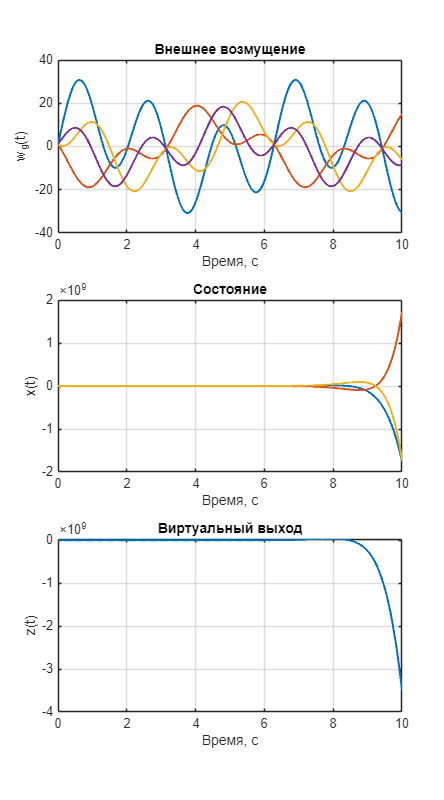

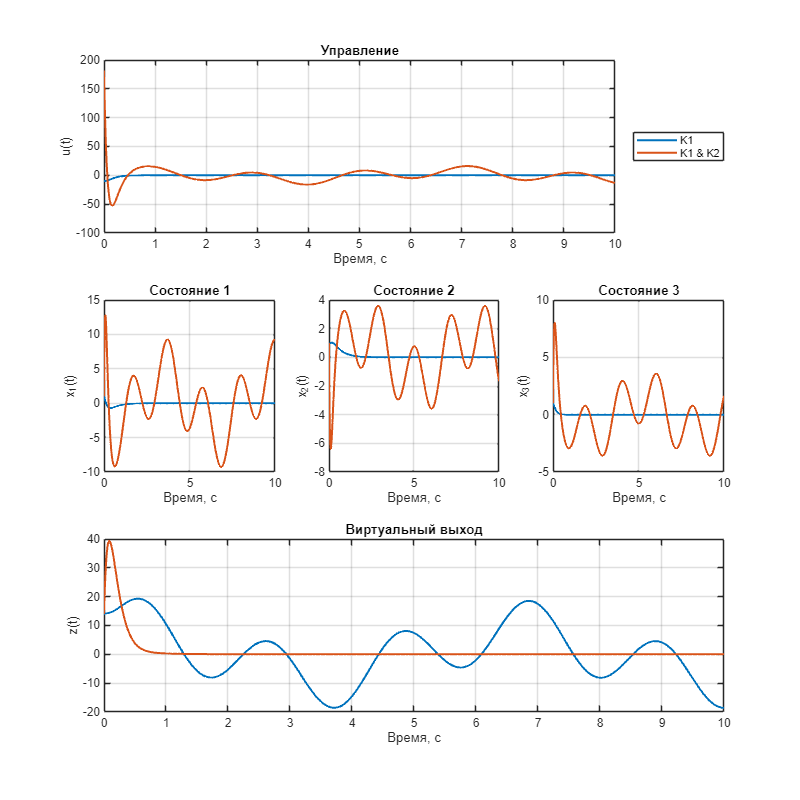

x0 = [1; 1; 1];
wg0 = [1; 1; 1; 1];
sim_sys2(A, B, K, K2, G, x0, wg0, 10);

## Задание 3. Слежение и компенсация по выходу.